## Basal Resampling Illustration

This script illustrates basal rate resampling in different scenarios.

%   Author: Jan Wrede
%   Date: 2025-10-22
%   
%   This file is part of the larger AIDIF-toolbox project and is licensed 
%       under the MIT license. A copy of the MIT License can be found in 
%       the project's root directory.
%
%   Copyright (c) year, AIDIF
%   All rights reserved

**Scenario 1**: Perfectly aligned to 5 minute intervals, Fixed Rate

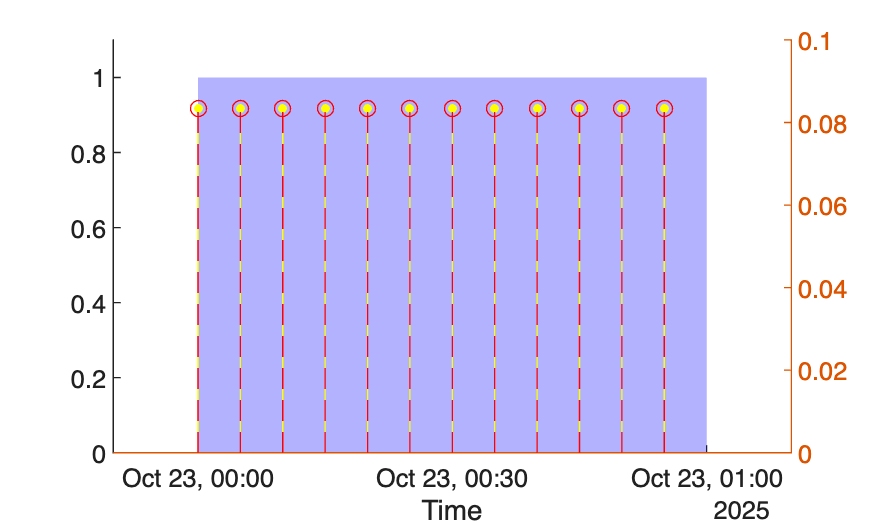

timestamps = datetime("today"):minutes(30):start+minutes(60);
basal_rates = ones(size(timestamps)); 
basal_rates = timetable(timestamps', basal_rates', 'VariableNames', {'basal_rate'});
resampleAndDraw(basal_rates);

**Scenario 2**: Perfectly aligned to 5 minute intervals, Change from 0 to 1 back to zero.

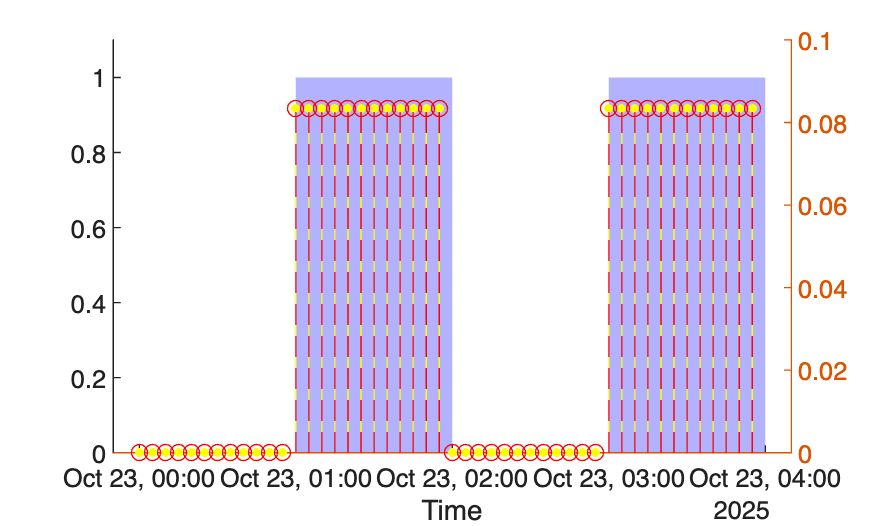

timestamps = datetime("today"):minutes(60):start+hours(4);
basal_rates = ones(size(timestamps)); basal_rates(1:2:length(basal_rates))=0;
basal_rates = timetable(timestamps', basal_rates', 'VariableNames', {'basal_rate'});
resampleAndDraw(basal_rates)

**Scenario 3**: Not Perfectly aligned, Fixed basal rate (1U/h) 

For the first sample, delivery happend for1 minute (1/60), for the last sample, delivery stops after 4 minutes (4/60)

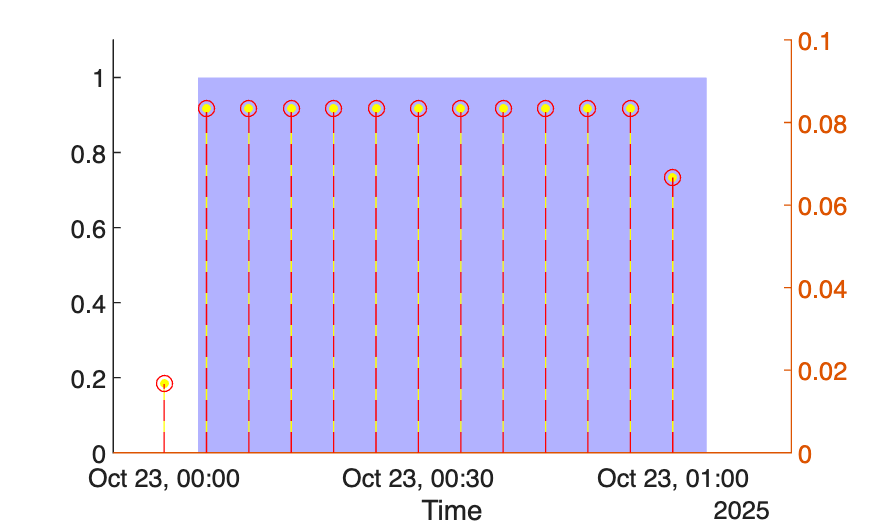

timestamps = datetime("today") + [minutes(4),minutes(64)];
basal_rates = [1,0];
basal_rates = timetable(timestamps', basal_rates', 'VariableNames', {'basal_rate'});
resampleAndDraw(basal_rates);

**Scenario 4**: Not perfectly aligned, and multiple values within 5 minutes

1 minute delivery of 1U/h + 1 minute delivery of 2U/h = 3/60 = 0.5U

timestamps = datetime("today") + minutes([0,3,4,5]);
basal_rates = [0,1,2,0]

basal_rates =      0     1     2     0


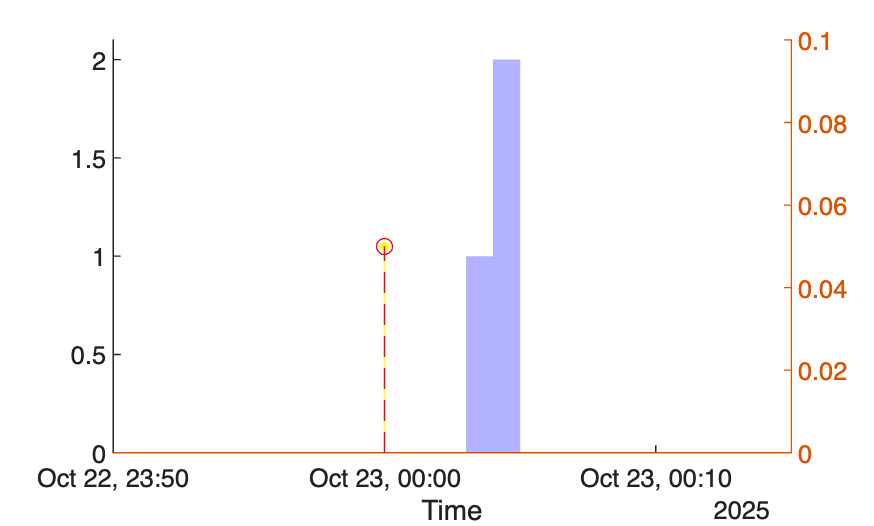

basal_rates = timetable(timestamps', basal_rates', 'VariableNames', {'basal_rate'});
resampleAndDraw(basal_rates);

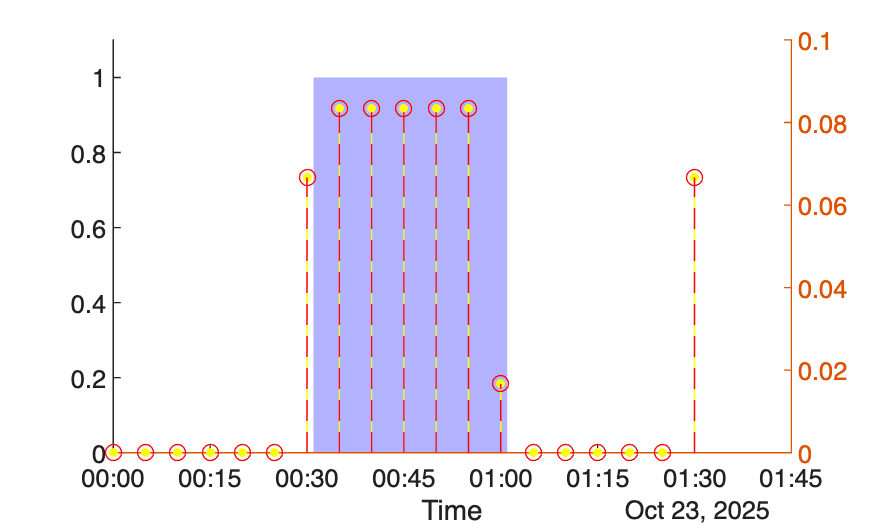

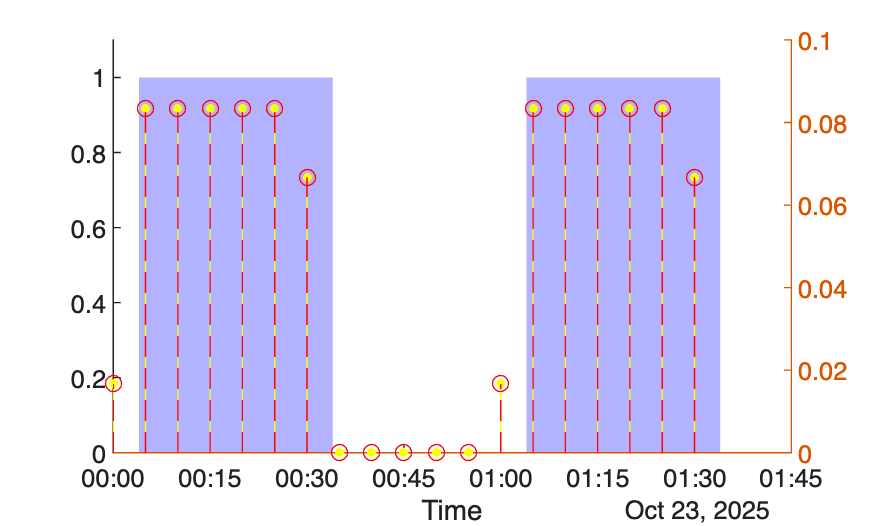

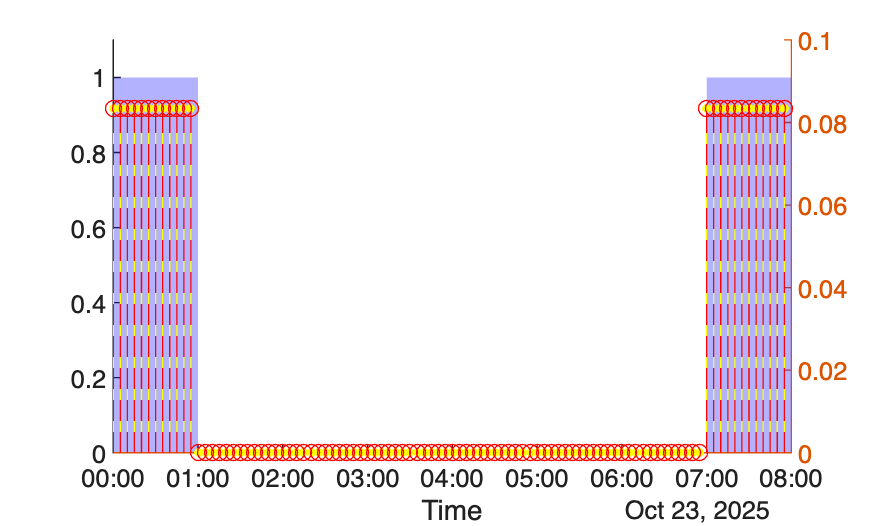

function resampleAndDraw(tt)

    %resample
    ttResampled = AIDIF.interpolateBasal(tt);
    
    %draw irregular basal rates
    clf; hold on; 
    [xs, ys] = stairs(tt.Time, tt.basal_rate);
    area(xs ,ys ,'FaceAlpha', 0.3, 'EdgeColor', 'none','FaceColor','blue',DisplayName='Basal Rate');
    ylim([0, max(tt.basal_rate) + 0.1]);
    %legend()
    
    %draw regular basal rates (resampled)
    yyaxis('right')
    stem(ttResampled,"Time","InsulinDelivery",Color='yellow',Marker='.',MarkerSize=10,DisplayName='deliveries')
    valid = AIDIF.findGaps(tt,ttResampled,2);
    isequal(tt.Time, ttResampled.Time); %sanity check
    ttResampled.Valid = valid.Valid;
    
    % Scatter plot NaN values in red
    nan_indices = isnan(ttResampled.InsulinDelivery);
    stem(ttResampled, 'Time', 'InsulinDelivery','Color','red'); 
    scatter(ttResampled.Time(nan_indices), zeros(sum(nan_indices),1), 'filled', 'x', 'MarkerEdgeColor', 'red');
    
    ylim([0,5/60 *1.2]);
    hold off;
    xlim([min(tt.Time)-minutes(10), max(tt.Time)+minutes(10)])
end
